# Example 4: Using Custom Functions to Mix Multiple TPMS

## Defining a unit cell parametrically

Similar to shown in example 1, the parameters for the TPMS should be defined. 

clear variables;
TYPE = "surface"; % Types: "network","surface","single", "double", "lattice"
V1 = 0.5; % Geometry Parameter 1
V2 = 0; % Geometry Parameter 2
RES = [30 30 30]; % Resolution - (number of voxels per edge in x,y,z)
L = 1; % Unit cell size in mm
R = [0 0 0]; % Euler rotation defined as [Rx Ry Rz] in degrees
B = [0 0 0]; % Phase shift/translation [Bx By Bz] in mm
N = [2 2 2]; % Number of unit cells in X,Y,Z
VOLUME = bulkSize('box',L.*N); % Box centered at origin with [lx, ly, lz]

% Use inputs to create the transform object
if verLessThan('matlab', '9.13') % Compatability for older versions of matlab
    TFORM = affine3d([L 0 0 B(1); 0 L 0 B(2); 0 0 L B(3); 0 0 0 1]'); % Definate an affine3d transform here using size and phase shift
else
    TFORM = simtform3d(L,R,B); % Other types of transforms can be defined - this example uses a similarity transform
end

To create a custom function, the equations must be defined individually. They can then be mixed using a weighting function (W1). 

% EQ1 is the Gyroid TPMS
EQ1 = @(x,y,z) (cos(2*pi*x).*sin(2*pi*y)+cos(2*pi*y).*sin(2*pi*z)+cos(2*pi*z).*sin(2*pi*x)); %Gyroid Equation

% EQ 2 is the primitive TPMS
EQ2 = @(x,y,z) (cos(2*pi*x)+cos(2*pi*y)+cos(2*pi*z));

% TPMS Type weighting Function (Must Range from 0 to 1), 
% here a sigmoid function is used with slope parameter 4
W1 = @(x,y,z) 1./(1+exp(4*x)); 

% Symbolics can be defined to create the custom matlabFunction
syms x y z;
EQMIXED = matlabFunction(W1(x,y,z).*EQ1(x,y,z)+(1-W1(x,y,z)).*EQ2(x,y,z)); % Creating the function
EQUATION = func2str(EQMIXED); % Combined function converted to string-type 

Finally, as shown before the unit cell is created, computed and plotted. (Note that here no inputs are used for compute, resulting in the default setup, with no curvature or mechanical analysis steps). Ad

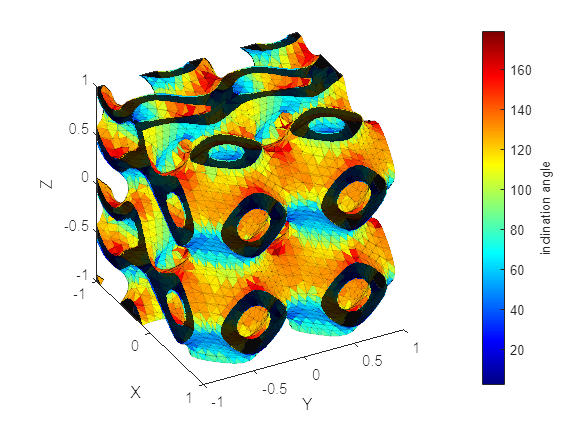

% Create the unit cell: myCell = UnitCell(TYPE,EQUATION,V1,V2,RES,TFORM,VOLUME);
% Any number of inputs may be left without an input: myCell = UnitCell();
% resulting in a gyroid network structure
myCell = UnitCell(TYPE,EQUATION,V1,V2,RES,TFORM,VOLUME);
myCell = myCell.compute();
axesSurface = myCell.plot("SurfaceMesh","inclination angle");